Promentilla, Jose Mikhael Uriel

Dela Torre, Alexczar

## Speech Signal Information

Utterance: "Tutugtug ba si Francisco?"

SampleRate: 16000

TotalSamples: 28926

Duration: 1.8079

Possible Vowel Sounds: 8

## Determining Voiced and Unvoiced Segments

Zero-crossings rate and Short-time energy are indicators for determining voiced and unvoiced segments. 

Because Voiced speech is in a state of excitation and periodicity, voiced speech can be identified to have low zero-crossings rate. Also due to this periodicity, these segments are noted to have high energy (R, B.K., S, & Barkana, 2008).

Meanwhile, unvoiced speech is in a state of turbulence and is resembles noise-like pulses. Therefore, unvoiced speech has the quality of having a high zero-crossing rate. Because of this, unvoiced speech also has low energy.

This then leads to the conditions in determining voiced and unvoiced segments. If the zero-crossing rate is low and the energy is high, then the segment will be classified as a voiced segment. Otherwise, when the zero-crossing rate is high and the energy is low, the segment will be classified as an unvoiced segment. In this machine problem, no distinctions will be made between silent and unvoiced segments.

The threshold was emulated from the following:

"For this application rate at which zero crossing occurs was calculated by taking a window of 20 ms and for the voiced region of the speech signal it was observed that zero crossing rate was always less than 0.1 and for the silence region it was between 0.1 and 0.3. For the unvoiced region ZCR was observed to be greater than 0.3 as shown in Figure 1."  (Sharma & Kiran Rajpoot, 2013)

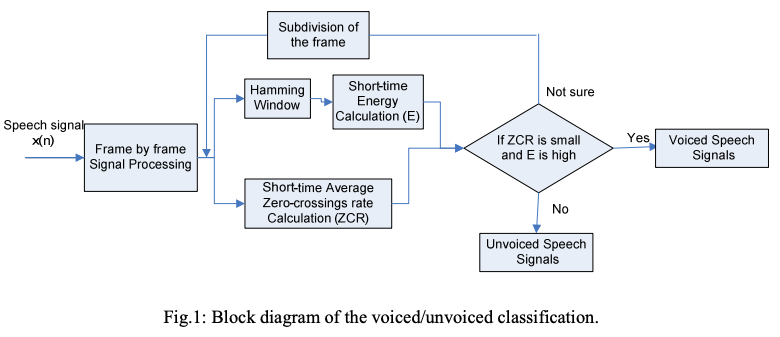

R, Bachu & B.K., Adapa & S, Kopparthi & Barkana, Buket. (2008). Separation of Voiced and Unvoiced Speech Signals using Energy and Zero Crossing Rate.

Sharma, Poonam & Kiran Rajpoot, Abha. (2013). Automatic Identification of Silence, Unvoiced and Voiced Chunks in Speech. Computer Science & Information Technology. 3. 87-96. 10.5121/csit.2013.3509. 

# Pitch Detection

Pitch is a property of a sound signal that allows it to be ordered due to its frequency. It is the perception of highness or lowness of a sound. Although frequency determines the pitch or how a sound is perceived, frequency is not pitch itself. Frequency is simply highly correlated with pitch. Pitch detection then is the process of detecting the pitch of a sound is, and specifically, the fundamental frequency (f0) of a sound is. The fundamental frequency is the lowest frequency of a sound signal and serves as the primary indicator for pitch. Pitch detection is a useful method that has relevant applications in speech recognition, emotion detection, sound transformations, and music transcriptions.

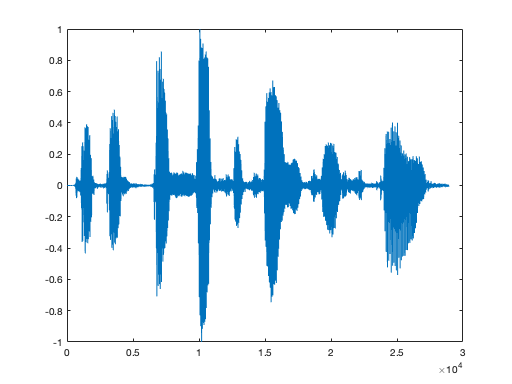

% Read the file
filename = 'speech_MP2.wav';
[signal,fs] = audioread(filename);
info = audioinfo(filename);
signalplot = figure; plot(signal); 

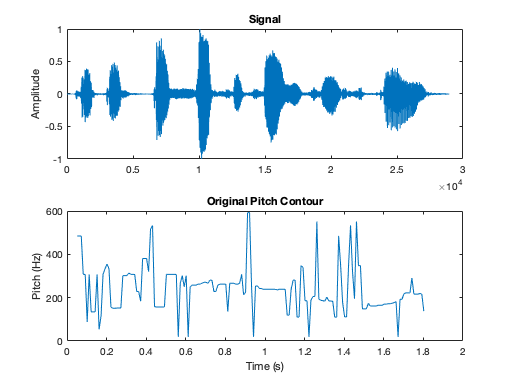


% Split/Segment into Frames with Overlapping 
rate = fs; %16000 per second gotten from info
duration = 0.05; %50ms in seconds
overlap = rate * 0.04; %total samples in 40ms
framelen = rate * duration; %=800 SAMPLES of length by 181 FRAMES
N = length(signal);
num_frames = floor(N/framelen);
allframes = buffer(signal,framelen,overlap);
% allframesplot = figure; plot(allframes); 

[row, col] = size(allframes);

% Determining Voiced or Unvoiced Segment
zcrlist = NaN(1, col);
stelist = NaN(1, col);
vuvlist = zeros(1, col);
% for each frame
for i = 1:col
    % get the zero crossing rate
    zcrlist(i) = ZCR(allframes(:, i));
    % get the short time energy
    stelist(i) = sum(buffer(allframes(:, i).^2, 1));
    
    % if ZCR is small and E is high then its Voiced (1)
    if zcrlist(i) < 0.1 & stelist(i) > 1
        vuvlist(i) = 1; % 1 means voiced
    end
end


% Setting Unvoiced Segments to 0
for i = 1:col
    if vuvlist(i) == 0 %if unvoiced
        allframes(:, i) = 0;
    end
end

% [audioIn,fs] = audioread('speech_MP2.wav');
[f0,idx] = pitch(signal,fs, 'Range',[10,700],'Method','CEP'); 
%the fs range is like a window, the bigger the less segments
%CEP range is from 7.8~399 
% [f0frame,idxframe] = pitch(allframes(:, 104),fs-1000, 'Range',[10,399],'Method','CEP');
f0list = zeros(col, 1);
idxlist = zeros(col, 1);
% Cepstrum Pitch Detection Per Frame
for i = 1:col
    if vuvlist(i) == 1 %if voiced
        f0list(i) = pitch(allframes(:, i),fs-1000, 'Range',[10,700],'Method','CEP');
    end
end

% PLOTTING

ampliplot = figure;
subplot(2,1,1)
plot(signal)
ylabel('Amplitude')
title('Signal')

t = idx/fs;
subplot(2,1,2)
plot(t,f0)
ylabel('Pitch (Hz)')
xlabel('Time (s)')
title('Original Pitch Contour')


modsignal = figure

modsignal =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [427 306 512 384]
       Units: 'pixels'

  Show all properties


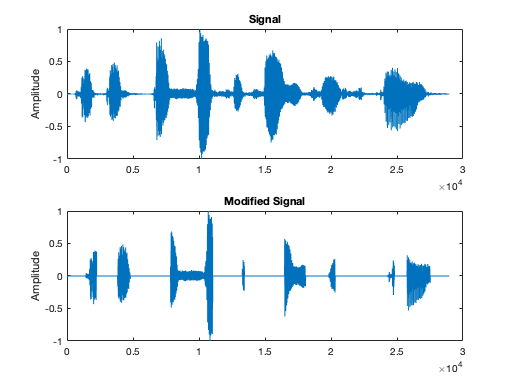

subplot(2,1,1)
subplot(2,1,1)
plot(signal)
ylabel('Amplitude')
title('Signal')

newsignal = [];
for i = 1:col
    newsignal = cat(1, newsignal, allframes(1:160, i));
end
subplot(2,1,2)
plot(newsignal)
ylabel('Amplitude')
title('Modified Signal')

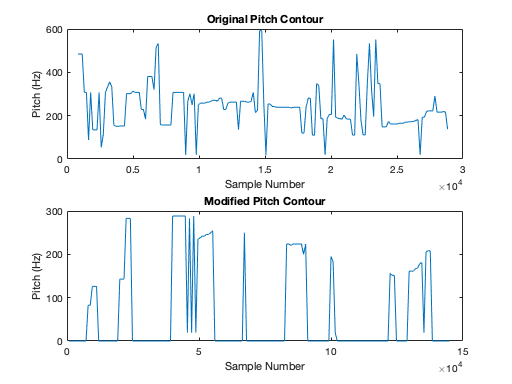


pitchcontourplot = figure;
subplot(2,1,1)
plot(idx,f0)
ylabel('Pitch (Hz)')
xlabel('Sample Number')
title('Original Pitch Contour')

subplot(2,1,2)
plot((1:181).*framelen,f0list)
ylabel('Pitch (Hz)')
xlabel('Sample Number')
title('Modified Pitch Contour')

## Pitch Detection Algorithm

The pitch detection algorithm selected is the cepstrum method. The cepstrum method is a popular choice in benchmarking for pitch detection methods due to its establishment as far as 1967. The cepstrum method is a frequency domain method. Pitch detection is done by taking the FFT of IFT of the logarithm-scaled spectrum of the signal. The power cepstrum then exhibits peaks that represents frequency periods that can be used to identify the fundamental frequency. The cepstrum method was chosen because it is a popular choice within different studies in pitch detection and would serve as a good benchmark in future studies.

## Vowel Sound Class Analysis

Based from the modified pitch contour there are 8 defining pitches. The time stamps in which the peaks occurred is the following:

- 0.1~0.2 (tu)

- 0.3~0.4 (tug)

- 0.5~0.6 (tug)

- 0.82~0.88 (ba)

- 1~1.1 (si)

- 1.1~1.2 (Fran)

- 1.23~1.25 (cis)

- 1.6~1.7 (co)

Based from the results, it can be hypothesized that there is a correlation between vowel sounds and pitches. It can be observed in the modified pitch contour, the third peak is wider and taller than most. It is also observed that it has the highest fundamental frequency. Analyzing the uttered phrase; "tutugtug", is increasing in pitch for each syllable, resulting into an increasing fundamental frequency, with the third being of the highest. In contrast "si Francisco", is decreasing in pitch for each syllable, resulting into the fall and low points on the latter parts of the modified pitch contour and fundamental frequency.

## PRAAT

### Extracted Voiced Unvoiced

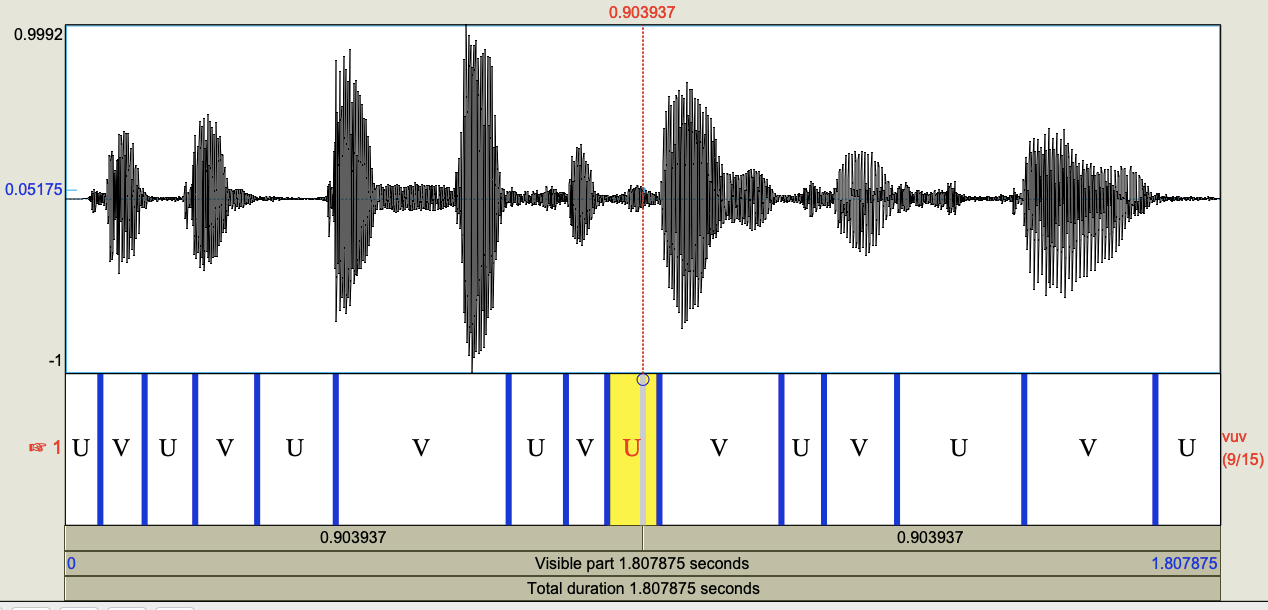

### Extracted Pitch

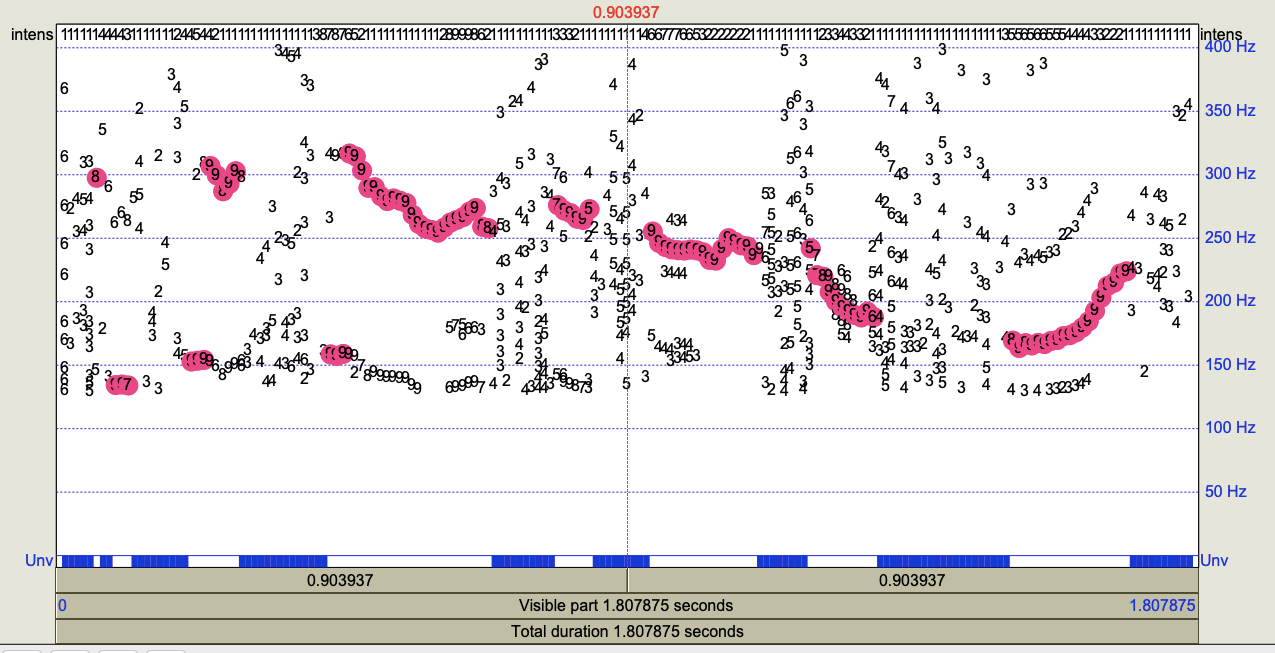

### Signal with Pitch

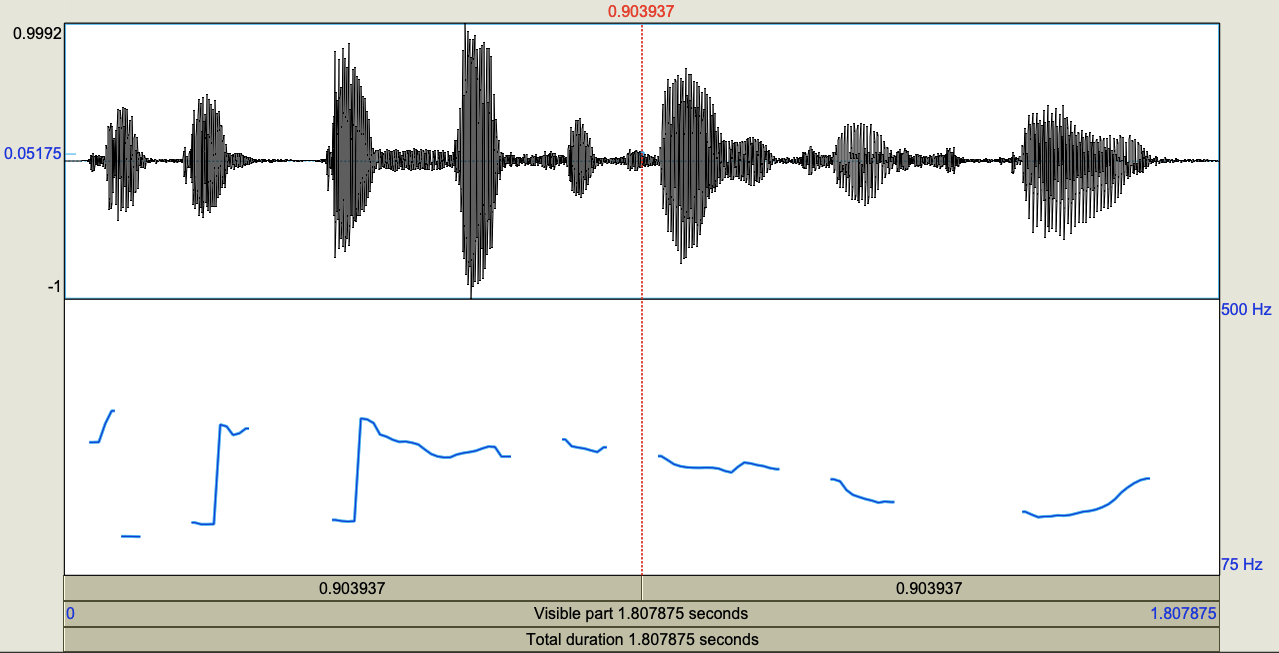

Based from the pitch contours, the result further supports the hypothesis that vowel sounds are correlated with pitch. Although there are only 7 lines in the pitch contour (not including the 2nd line that has a low frequency), it can be reasoned out that the 3rd long line is a connection of 2 pitches. Considering that, there would be 8 detectable pitches which also matches the time stamps in which the vowels were uttered. As it has been also inferred from the first analysis, the phrase "si Francisco" is falling in fundamental frequency with each syllable. Overall, the results from PRAAT and the results of the first analysis generally supports the same hypothesis.

# Formant Detection

Formants are energies surrounding a frequency. Formants can easily be identified by using a spectrogram. The darker parts represent high energy that possibly indicate a formant frequency. Formant frequencies can also be identified by plotting a point in time in the spectrum domain. The peaks can be identified to be the formant frequencies. Formant frequencies are also connected to harmonics 

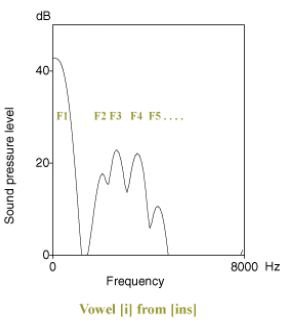 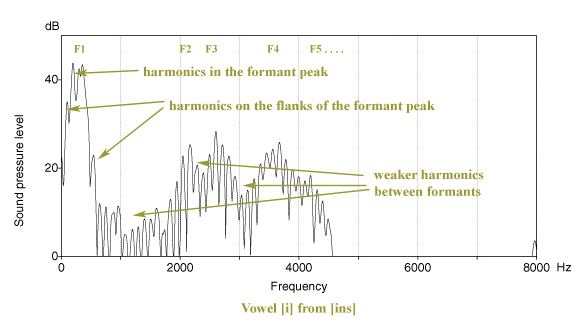

## Formant Detection Algorithm

Two implementation methods was done to detect the formant frequencies. Both use linear prediction as its basis. The first version uses linear predictive coding (LPC) to estimate the formants. LPC uses linear predictive models and the roots of the prediction polynomial to estimate the formant frequencies. The second version uses what is know as source-filter separation to estimate formants. The linear predictive models of the signal are passed through a recursive infinite impulse response (IIR) filter. Using the filter coefficients as a polynomial and solving for its roots would lead to the estimation of the formant frequencies.

The use of linear predictions was chosen as part of the algorithm because it simplifies the problem into solvable equations and still retains high accuracy estimates. LPC analysis is used for modeling vowels, encoding speech, and signal representation in compressed forms. LPC is also connected to two models: source-filter model and simplified vocal tract model.

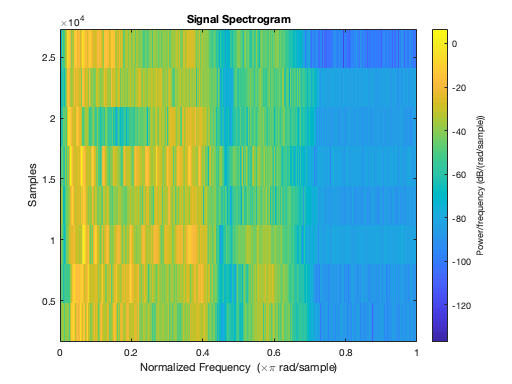

% Read the file
filename = 'speech_MP2.wav';
[signal,fs] = audioread(filename);
info = audioinfo(filename);
% signalplot = figure; plot(signal); 

% Split/Segment into Frames with Overlapping 
rate = fs; %16000 per second gotten from info
duration = 0.05; %50ms in seconds
overlap = rate * 0.04; %total samples in 40ms
framelen = rate * duration; %=800 SAMPLES of length by 181 FRAMES
N = length(signal);
num_frames = floor(N/framelen);
allframes = buffer(signal,framelen,overlap);
% allframesplot = figure; plot(allframes); 

% Determining Voiced or Unvoiced Segment
[row, col] = size(allframes);
zcrlist = NaN(1, col);
stelist = NaN(1, col);
vuvlist = zeros(1, col);
% for each frame
for i = 1:col
    % get the zero crossing rate
    zcrlist(i) = ZCR(allframes(:, i));
    % get the short time energy
    stelist(i) = sum(buffer(allframes(:, i).^2, 1));
    
    % if ZCR is small and E is high then its Voiced (1)
    if zcrlist(i) < 0.1 & stelist(i) > 1
        vuvlist(i) = 1; % 1 means voiced
    end
end

spectogramplot = figure;
spectrogram(signal);
title('Signal Spectrogram');

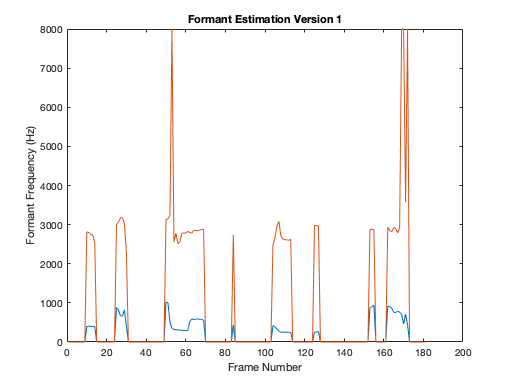


[row, col] = size(allframes);

% For each frame, Estimate a Formant VERSION 1
formantlist = zeros(2, col);
for i = 1:col
    if vuvlist(i) == 1 % its a voiced segment
        x1 = allframes(:, i);
        preemph = [1 0.63];
        x1 = filter(1,preemph,x1);
        A = lpc(x1,8);
        rts = roots(A);
        rts = rts(imag(rts)>=0);
        angz = atan2(imag(rts),real(rts));
        [frqs,indices] = sort(angz.*((fs)/(2*pi)));
        bw = -1/2*((fs)/(2*pi))*log(abs(rts(indices)));
        nn = 1;
        for kk = 1:length(frqs)
            if (frqs(kk) > 90 && bw(kk) <400)
                formants(nn) = frqs(kk);
                nn = nn+1;
            end
        end
        formantlist(1:2, i) = formants(1, 1:2);
    end
end
formantplot1 = figure; 
plot(1:181, formantlist);
ylabel('Formant Frequency (Hz)');
xlabel('Frame Number');
title('Formant Estimation Version 1');

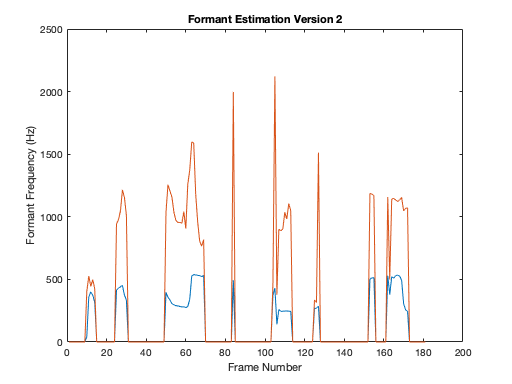


% For each frame, Estimate a Formant VERSION 2
formantlist2 = zeros(2, col);
for i = 1:col
    if vuvlist(i) == 1 % its a voiced segment
        x = allframes(:, i);
        % get Linear prediction filter
        ncoeff=2+fs/1000;           % rule of thumb for formant estimation
        a=lpc(x,ncoeff);
        %
        % plot frequency response
    %     [h,f]=freqz(1,a,512,fs);
    %     subplot(2,1,2);
    %     plot(f,20*log10(abs(h)+eps));
    %     legend('LP Filter');
    %     xlabel('Frequency (Hz)');
    %     ylabel('Gain (dB)');

        % find frequencies by root-solving
        r=roots(a);                  % find roots of polynomial a
        r=r(imag(r)>0.01);           % only look for roots >0Hz up to fs/2
        ffreq=sort(atan2(imag(r),real(r))*fs/(2*pi));

                                     % convert to Hz and sort
        formantlist2(1:2, i) = ffreq(1:2, 1);

    %     for i=1:length(ffreq)
    %         fprintf('Formant %d Frequency %.1f\n',i,ffreq(i));
    %     end
    end
end
formantplot2 = figure; 
plot(1:181, formantlist2);
ylabel('Formant Frequency (Hz)');
xlabel('Frame Number');
title('Formant Estimation Version 2');

## Vowel Sound Class Analysis

It can be observed, as the same in the pitch detection analysis, that there are generally 8 distinguishable peaks in formant frequencies that correspond with the time stamps of the vowel uttered. Although there is an interesting observation to be made. In the first place, the segments where formant estimations are made are all voiced segments. As you might recall, one of the conditions in determining a segment as voiced is the short-time energy on it. If the short-time energy was computed to be high, it would be classified as a voiced segment. With formant frequencies as representations of energy, it be predicted that voiced segments would have high estimations for formant frequencies. The highest estimation for the formant frequencies comes from the third peak which corresponds with the syllable "tug". It can be noted that not only is the pitch increasing in the phrase "tutugtug" but also in emphasis towards the end. This emphasis is then translated to energy. This might possibly explain why it has a higher estimated formant frequency than others. Although the estimations shown by version 1 and version 2 are different, both versions can be lead a hypothesis. In version 1, the next highest formant frequency occurs in the phrase part "(Francis)co". The "co" part has a longer sounding vowel than the others. The same applies to version 2. In version 2's case, the next highest formant frequency occurs in the phrase part "ba". From this, it can be hypothesized that longer sounding vowels contain more energy, and therefore higher formant frequencies.

## PRAAT

### Spectogram and Formant

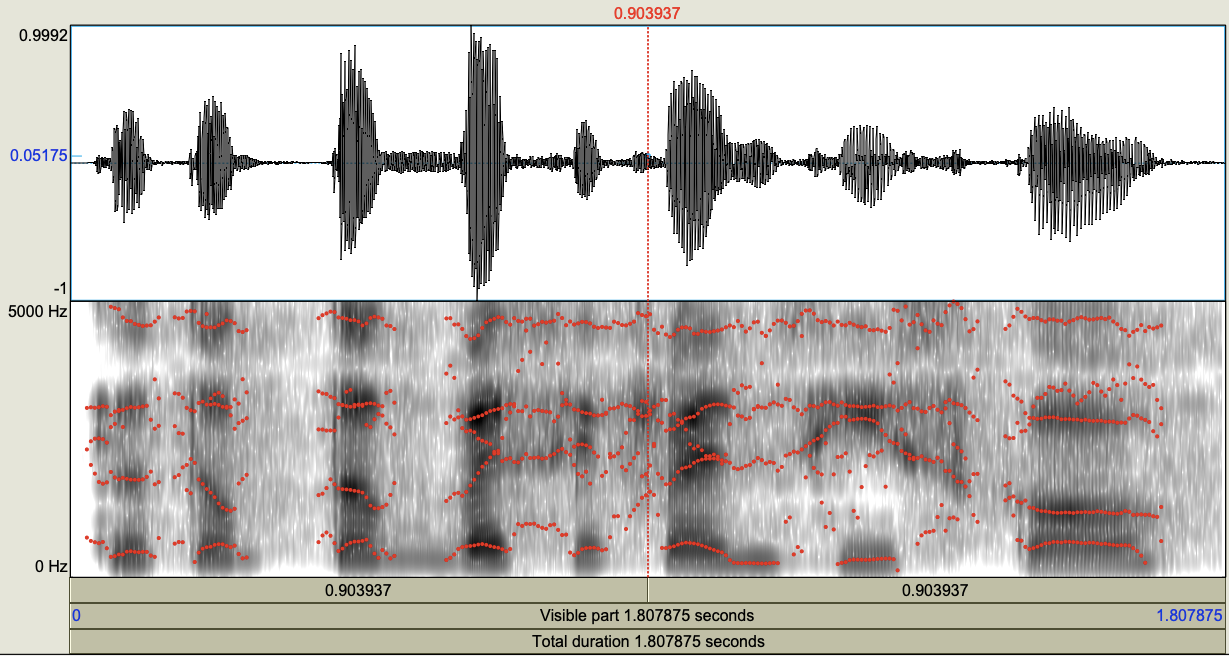

It can be observed that little to no formants exist in the unvoiced segments while the voiced segments not only show formants but also show an increasing trend during the voiced segment. As to the previous hypothesis that longer sounding vowels would have higher formants, the results show otherwise. If the hypothesis were true, then the phrase part "co" would have an increasing trend in formant frequencies. This has led to the revision that perhaps high energy utterances merely have longer sounds. The distinction to be made here is that it's not the longer vowel sounds causing high energy/high formant frequency, but the coincidence of high energy causing longer sounds. Based from this graph there seems to be little correlation between pitch and formant frequencies. The last but most important conclusion to be made from analysis is the importance of classifying voiced and unvoiced segments. The classification of voiced and unvoiced segments are of high importance because it is highly correlated with pitch and formant frequencies and can be used as a feature for estimations.